# Make matrix/graph

m = [100; 100; 20; 10; 5; 25];
n = [80; 20; 100; 10; 5; 25];
p = 0.7;
q = 0.4;

[G, k, X0, M,N ] = planted_dense2(m, n, p, q);

u_beg =      1
   101
   201
   221
   231
   236
   261


v_beg =      1
    81
   101
   201
   211
   216
   241


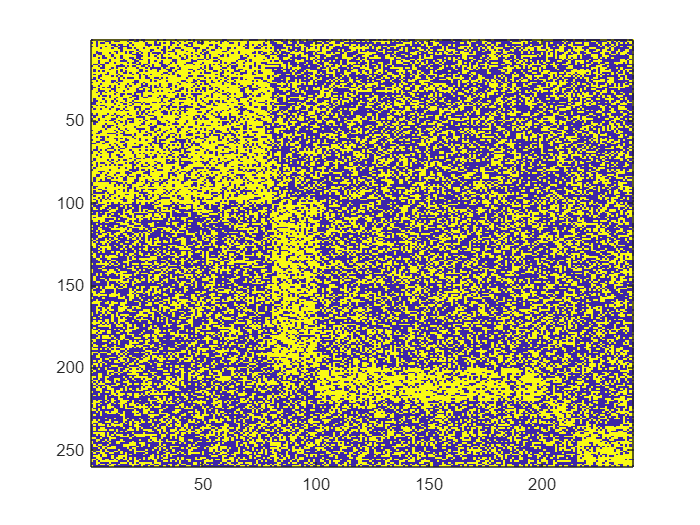


figure
imagesc(G)

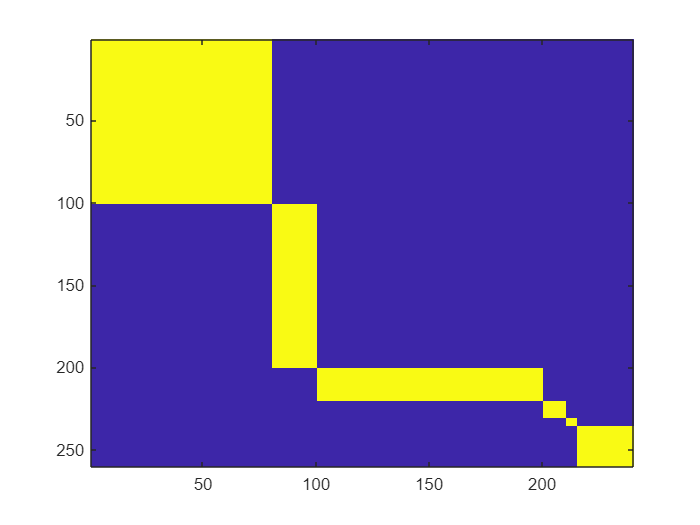

figure
imagesc(X0)

## Attempt to solve using Elastic net problem.

mm = m(1);
nn = n(1);
rho = 0.75;
gamma = (p - q)*min(mm, nn)/10;
% gamma = norm(1 -G)
tol = 1e-6;
maxiter = 5000;
quiet = false;
alpha = 0.5;

[u,v,X,fval, time,  x, y] = densub_en(G, mm,nn, gamma, alpha, rho, tol, maxiter, quiet);

 ********* iteration starts *********
 iter    1   fval     131154  dfeas   0.518392 pfeas    1.01721
 iter    2   fval    27906.5  dfeas   0.609187 pfeas    1.03875
 iter    3   fval    9525.04  dfeas   0.629026 pfeas    1.08828
 iter    4   fval    6206.74  dfeas   0.664166 pfeas    1.15762
 iter    5   fval    5803.23  dfeas   0.709168 pfeas    1.13556
 iter    6   fval    5890.54  dfeas    1.01341 pfeas    1.01818
 iter    7   fval      11949  dfeas    2.97034 pfeas   0.956188
 iter    8   fval    35251.9  dfeas    1.58609 pfeas   0.949893
 iter    9   fval    24300.2  dfeas   0.599134 pfeas   0.935188
 iter   10   fval    7515.49  dfeas   0.562517 pfeas   0.850996
 iter   11   fval    4019.28  dfeas   0.510598 pfeas    0.68903
 iter   12   fval    3150.26  dfeas   0.413418 pfeas    0.45982
 iter   13   fval    2887.37  dfeas   0.275892 pfeas   0.247327
 iter   14   fval    2795.77  dfeas   0.148396 pfeas   0.113947
 iter   15   fval    2761.29  dfeas  0.0683684 pfeas  0.0484304
 i

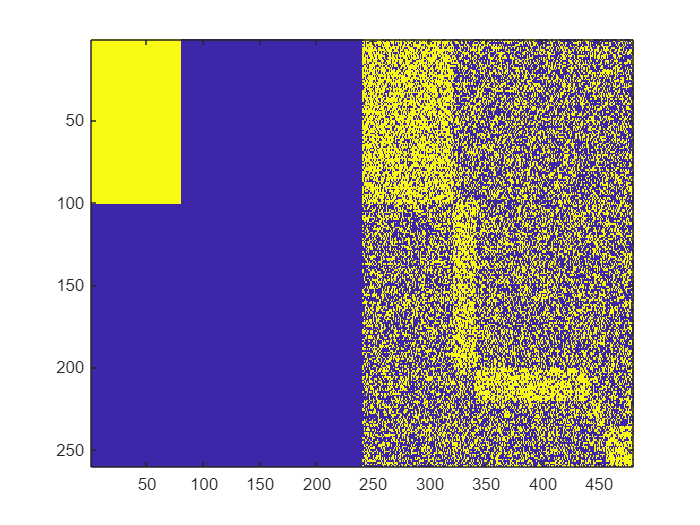


figure
imagesc([X, G])


% figure
% imagesc([u, v])

fprintf("norm A = %g\n", norm(G))

norm A = 116.387


fprintf("gamma = %g \n", gamma*(1-alpha))

gamma = 1.2 
